assert(isfile("DCS_3D_Plate.mlx"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

#### Electromagnet

EM.num = 1;
EM.inner_radius = 3.75e-3; % (m)
EM.outer_radius = 6.00e-3; % (m)
EM.length = 4.00e-3; % (m)
EM.Nturns = 60;

EM_pos = [0, 0, 6.5e-3]; % (m)
EM = SetPositionRotation(EM, EM_pos, [1,0,0], deg2rad(0));

#### Sensor

Sensor.num = 2;
Sensor.side_length = 1e-3;

Sensor_pos1 = EM_pos + [6.5e-3 0 -2e-3];
Sensor_pos2 = EM_pos + [-6.5e-3 0 -2e-3];
Sensor = SetPositionRotation(Sensor, [Sensor_pos1;Sensor_pos2], [1,0,0;1,0,0], [0;0]);
clear EM_pos Sensor_pos1 Sensor_pos2

#### Model

Model = struct;

vertex_file = 'Square_36mm_g6mm_node.inp';
element_file = 'Square_36mm_g6mm_element.inp';
Model = LoadModel3D(Model, vertex_file, element_file, 1e-3);

calculate geometry took 0.00 seconds


clear vertex_file element_file

Model.conductivity = 2.38e6 * ones(1,Model.num_elms); % (S/m)

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, EM);

build governing equation took 1.42 seconds
build constraint equation took 0.00 seconds


#### Solve in frequency domain

EM.frequency_domain.current = 1; % (A)
EM.frequency_domain.current_density = EM.frequency_domain.current * EM.Nturns / ((EM.outer_radius-EM.inner_radius)*EM.length); % (A/m^2)
EM.frequency_domain.angular_frequency = 2*pi*2000; % (rad/s)

[Model, EM, Sensor] = SolveFrequency3D(GoverningEquation, Model, EM, Sensor);


Solver stopped prematurely.

lsqlin stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.


Solver stopped prematurely.

lsqlin stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.

solve J took 0.02 seconds
solve B_E took 0.61 seconds
solve B_C took 0.00 seconds


#### Plot result

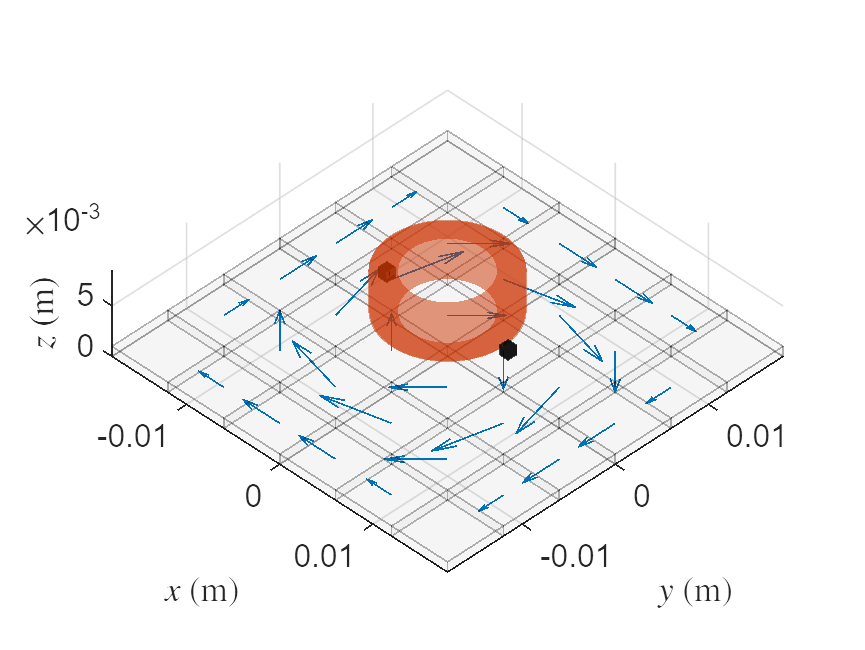

pos = Model.elms_center;
vec = real(Model.frequency_domain.J);
quiver3(pos(1,:),pos(2,:),pos(3,:), vec(1,:),vec(2,:),vec(3,:));
clear pos vec

PlotWorld3D(Model, EM, Sensor);